q = 8.375e-6;  s = 77.27;  w = 0.161;
f = @(t,u) [ s*(u(2)-u(1)*u(2)+u(1)-q*u(1)^2);...
    (-u(2)-u(1)*u(2)+u(3))/s; ...
    w*(u(1)-u(3)) ];

The `ode15s` solver is fast.

tic, [t,u] = ode15s(f,[0 6],[1,1,4]); toc

Elapsed time is 0.326304 seconds.


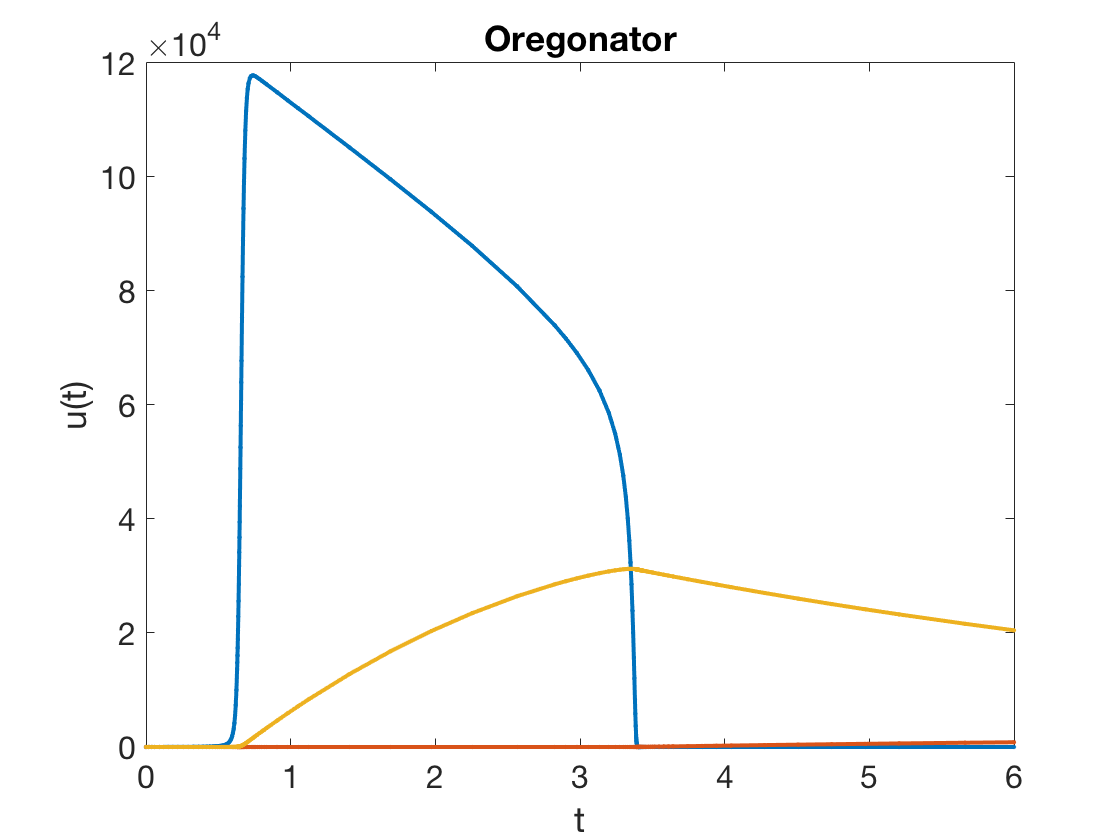

plot(t,u,'.-')
xlabel('t'), ylabel('u(t)')   % ignore this line
title('Oregonator')   % ignore this line

num_steps_ode15s = length(t)

num_steps_ode15s =      180       


You can see that `ode15s` takes small time steps only when some part of the solution is changing rapidly. However, the `ode45` solver, based on an explicit RK4 method, is much slower and takes more steps compared to  `ode15s`.

tic, [t,u] = ode45(f,[0 6],[1,1,4]); toc

Elapsed time is 2.573422 seconds.


num_steps_ode45 = length(t)

num_steps_ode45 =   113661       


Here is the Jacobian matrix at any value of $\mathbf{u}$. 

J = @(u) [ -s*(u(2)+1-2*q*u(1)), s*(1-u(1)), 0; ...
    -u(2)/s, (-1-u(1))/s, 1/s; ...
    w,0,-w];

During the early phase, the time steps seem fairly large. The eigenvalues around $t=1/2$ are 

i1 = find(t>0.5,1);   
lambda1 = eig( J(u(i1,:)) )

lambda1 =    -9089/65    
    -103/91    
   -4558/11921 


These are real and negative. Checking the stability region of RK4 along the negative real axis, we see that stability requires a maximum time step

maxstep1 = 2.8 / max(abs(lambda1))

maxstep1 =      182/9089  


The actual step size chosen by `ode45` was

step1 = t(i1+1) - t(i1)

step1 =      185/12909 


Later in the simulation, the steps seem quite small compared to the apparent rate of activity. We look near $t=4$:

i2 = find(t>4,1);   
lambda2 = eig( J(u(i2,:)) )

lambda2 =  -237069/13    
    -298/11513 
    -554/3441  


These are also real and negative. We compare the maximum and observed step sizes again:

maxstep2 = 2.8 / max(abs(lambda2))

maxstep2 =        9/58616 


step2 = t(i2+1) - t(i2)

step2 =        4/81849 
